clear all;
close all;
clc;

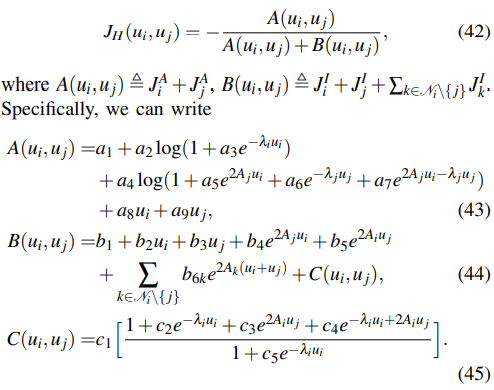

syms u_i u_j positive
ui = u_i; uj = u_j;
syms lambda_i lambda_j positive
li = lambda_i; lj = lambda_j;
syms A_i A_j positive
Ai = A_i; Aj = A_j;
syms a [1 9] real
syms b [1 5] real
syms b6 [1 2] real
syms A6 [1 2] positive
syms c [1 5] real


Assumptions on coefficients

assumeAlso(a2>0);
assumeAlso(a3<0 & a3>-1);
assumeAlso(a4>0);
assumeAlso(a5*a6>0);
assumeAlso(a7==-a5);
assumeAlso(a8>0);
assumeAlso(a9<0);

assumeAlso(b1<0);
assumeAlso(b2<0);
assumeAlso(b3<0);
assumeAlso(b4>0);
assumeAlso(b5>0);
assumeAlso(b6>0);

assumeAlso(c1<0);
assumeAlso(c2>0);
assumeAlso(c3<-1);
assumeAlso(c4<0);
assumeAlso(c5==a3);

Evaluation of functions

num = 1 + c2*exp(-li*ui) + c3*exp(2*Ai*uj) + c4*exp(-li*ui+2*Ai*uj);
den = 1 + c5*exp(-li*ui);
C = c1*num/den

$$C = \frac{c_{1}\,\left(c_{3}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+c_{2}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+c_{4}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}+1\right)}{c_{5}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+1}$$


Bpart1 = b1 + b2*ui + b3*uj + b4*exp(2*Aj*ui) + b5*exp(2*Ai*uj);
Bpart2 = sum(b6.*exp(2*A6*(u_i+u_j)));
B = Bpart1 + Bpart2 + C

$$B = b_{1}+b_{61}\,{\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)}+b_{62}\,{\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}+b_{2}\,u_{i}+b_{3}\,u_{j}+b_{4}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+b_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+\frac{c_{1}\,\left(c_{3}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+c_{2}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+c_{4}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}+1\right)}{c_{5}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+1}$$


Apart1 = a1 + a2*log(1+a3*exp(-li*ui)) + a8*ui + a9*uj;
Apart2 = 1 + a5*exp(2*Aj*ui) + a6*exp(-lj*uj) + a7*exp(2*Aj*ui-lj*uj);
A = Apart1 + a4*log(Apart2) 

$$A = a_{1}+a_{4}\,\log\left(a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+a_{6}\,{\mathrm{e}}^{-\lambda_{j}\,u_{j}}+a_{7}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}}+1\right)+a_{8}\,u_{i}+a_{9}\,u_{j}+a_{2}\,\log\left(a_{3}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+1\right)$$


J = -A/(A+B)

$$J = \begin{array}{l} -\frac{a_{1}+\sigma_{1}+a_{8}\,u_{i}+a_{9}\,u_{j}+\sigma_{2}}{a_{1}+b_{1}+\sigma_{1}+b_{61}\,{\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)}+b_{62}\,{\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}+a_{8}\,u_{i}+a_{9}\,u_{j}+b_{2}\,u_{i}+b_{3}\,u_{j}+b_{4}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+b_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+\sigma_{2}+\frac{c_{1}\,\left(c_{3}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+c_{2}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+c_{4}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}+1\right)}{c_{5}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+1}}\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\log\left(a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+a_{6}\,{\mathrm{e}}^{-\lambda_{j}\,u_{j}}+a_{7}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}}+1\right)\\ \sigma_{2}=a_{2}\,\log\left(a_{3}\,{\mathrm{e}}^{-\lambda_{i}\,u_{i}}+1\right) \end{array}$$


assumeAlso(A>0);
assumeAlso(B>0);

as = assumptions;

numOfSteps = 10000;

DAi = simplifyWell(diff(A,u_i),numOfSteps)

$$DAi = \begin{array}{l} \frac{a_{8}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{3}\,a_{6}\,a_{8}+a_{6}\,a_{8}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+a_{3}\,a_{8}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{2}\,a_{3}\,\lambda_{i}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{2}\,a_{3}\,a_{6}\,\lambda_{i}+a_{3}\,a_{7}\,a_{8}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,a_{8}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{3}\,a_{5}\,a_{8}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{5}\,a_{8}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{2}\,a_{3}\,a_{5}\,\lambda_{i}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+2\,A_{j}\,a_{4}\,a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+2\,A_{j}\,a_{3}\,a_{4}\,a_{7}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{2}\,a_{3}\,a_{7}\,\lambda_{i}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+2\,A_{j}\,a_{4}\,a_{7}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+2\,A_{j}\,a_{3}\,a_{4}\,a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}}{\left(a_{3}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}\right)\,\left(a_{6}+{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}} \end{array}$$

DAii = simplifyWell(diff(DAi,u_i),numOfSteps)

DAj = simplifyWell(diff(A,u_j),numOfSteps)

$$DAj = \begin{array}{l} \frac{a_{6}\,a_{9}+a_{9}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{4}\,a_{6}\,\lambda_{j}+a_{5}\,a_{9}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,a_{9}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}-a_{4}\,a_{7}\,\lambda_{j}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}}{a_{6}+{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}} \end{array}$$

DAjj = simplifyWell(diff(DAj,u_j),numOfSteps)

$$DAjj = \begin{array}{l} \frac{a_{4}\,a_{6}\,{\lambda_{j}}^{2}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{4}\,a_{7}\,{\lambda_{j}}^{2}\,\sigma_{1}\,{\mathrm{e}}^{2\,\lambda_{j}\,u_{j}}+a_{4}\,a_{5}\,a_{6}\,{\lambda_{j}}^{2}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{4}\,a_{5}\,a_{7}\,{\lambda_{j}}^{2}\,\sigma_{1}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{2\,\lambda_{j}\,u_{j}}}{{\left(a_{6}+{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}} \end{array}$$

DAij = simplifyWell(diff(DAi,u_j),numOfSteps)

$$DAij = -\frac{2\,A_{j}\,a_{4}\,a_{7}\,\lambda_{j}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}}\,{\mathrm{e}}^{2\,\lambda_{j}\,u_{j}}-2\,A_{j}\,a_{4}\,a_{5}\,a_{6}\,\lambda_{j}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}}{{\left(a_{6}+{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{7}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}-\lambda_{j}\,u_{j}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}+a_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{j}\,u_{j}}\right)}^{2}}$$


DBi = simplifyWell(diff(B,u_i),numOfSteps)

$$DBi = \begin{array}{l} \frac{b_{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+b_{2}\,{c_{5}}^{2}+2\,b_{2}\,c_{5}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{61}\,b_{61}\,{c_{5}}^{2}\,\sigma_{2}+2\,A_{62}\,b_{62}\,{c_{5}}^{2}\,\sigma_{1}+2\,A_{j}\,b_{4}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}-c_{1}\,c_{2}\,\lambda_{i}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+c_{1}\,c_{5}\,\lambda_{i}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{j}\,b_{4}\,{c_{5}}^{2}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+2\,A_{61}\,b_{61}\,\sigma_{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+2\,A_{62}\,b_{62}\,\sigma_{1}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}-c_{1}\,c_{4}\,\lambda_{i}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+4\,A_{61}\,b_{61}\,c_{5}\,\sigma_{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,A_{62}\,b_{62}\,c_{5}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,A_{j}\,b_{4}\,c_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+c_{1}\,c_{3}\,c_{5}\,\lambda_{i}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}}{{\left(c_{5}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{2}={\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)} \end{array}$$

DBii = simplifyWell(diff(DBi,u_i),numOfSteps)

$$DBii = \begin{array}{l} \frac{4\,{A_{61}}^{2}\,b_{61}\,\sigma_{2}\,{\mathrm{e}}^{3\,\lambda_{i}\,u_{i}}+4\,{A_{62}}^{2}\,b_{62}\,\sigma_{1}\,{\mathrm{e}}^{3\,\lambda_{i}\,u_{i}}+4\,{A_{61}}^{2}\,b_{61}\,{c_{5}}^{3}\,\sigma_{2}+4\,{A_{62}}^{2}\,b_{62}\,{c_{5}}^{3}\,\sigma_{1}+4\,{A_{j}}^{2}\,b_{4}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{3\,\lambda_{i}\,u_{i}}+c_{1}\,c_{2}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}-c_{1}\,c_{5}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+4\,{A_{j}}^{2}\,b_{4}\,{c_{5}}^{3}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}+c_{1}\,{c_{5}}^{2}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+12\,{A_{61}}^{2}\,b_{61}\,{c_{5}}^{2}\,\sigma_{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+12\,{A_{62}}^{2}\,b_{62}\,{c_{5}}^{2}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+12\,{A_{j}}^{2}\,b_{4}\,{c_{5}}^{2}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+c_{1}\,c_{4}\,{\lambda_{i}}^{2}\,\sigma_{3}\,{\mathrm{e}}^{3\,\lambda_{i}\,u_{i}}+12\,{A_{61}}^{2}\,b_{61}\,c_{5}\,\sigma_{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+12\,{A_{62}}^{2}\,b_{62}\,c_{5}\,\sigma_{1}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+12\,{A_{j}}^{2}\,b_{4}\,c_{5}\,{\mathrm{e}}^{2\,A_{j}\,u_{i}}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}-c_{1}\,c_{2}\,c_{5}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}-c_{1}\,c_{4}\,c_{5}\,{\lambda_{i}}^{2}\,\sigma_{3}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}-c_{1}\,c_{3}\,c_{5}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+c_{1}\,c_{3}\,{c_{5}}^{2}\,{\lambda_{i}}^{2}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}}{{\left(c_{5}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}\right)}^{3}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{2}={\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{3}={\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}} \end{array}$$

DBj = simplifyWell(diff(B,u_j),numOfSteps)

$$DBj = \begin{array}{l} \frac{b_{3}\,c_{5}+b_{3}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{i}\,b_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{61}\,b_{61}\,c_{5}\,\sigma_{2}+2\,A_{62}\,b_{62}\,c_{5}\,\sigma_{1}+2\,A_{i}\,b_{5}\,c_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+2\,A_{61}\,b_{61}\,\sigma_{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{62}\,b_{62}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{i}\,c_{1}\,c_{4}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+2\,A_{i}\,c_{1}\,c_{3}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}}{c_{5}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{2}={\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)} \end{array}$$

DBjj = simplifyWell(diff(DBj,u_j),numOfSteps)

$$DBjj = \begin{array}{l} \frac{4\,{A_{61}}^{2}\,b_{61}\,c_{5}\,\sigma_{2}+4\,{A_{62}}^{2}\,b_{62}\,c_{5}\,\sigma_{1}+4\,{A_{i}}^{2}\,b_{5}\,c_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}+4\,{A_{61}}^{2}\,b_{61}\,\sigma_{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,{A_{62}}^{2}\,b_{62}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,{A_{i}}^{2}\,b_{5}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,{A_{i}}^{2}\,c_{1}\,c_{4}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+4\,{A_{i}}^{2}\,c_{1}\,c_{3}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}}{c_{5}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{2}={\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)} \end{array}$$

DBij = simplifyWell(diff(DBi,u_j),numOfSteps)

$$DBij = \begin{array}{l} \frac{4\,{A_{61}}^{2}\,b_{61}\,\sigma_{2}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+4\,{A_{62}}^{2}\,b_{62}\,\sigma_{1}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+4\,{A_{61}}^{2}\,b_{61}\,{c_{5}}^{2}\,\sigma_{2}+4\,{A_{62}}^{2}\,b_{62}\,{c_{5}}^{2}\,\sigma_{1}+8\,{A_{61}}^{2}\,b_{61}\,c_{5}\,\sigma_{2}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}+8\,{A_{62}}^{2}\,b_{62}\,c_{5}\,\sigma_{1}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}-2\,A_{i}\,c_{1}\,c_{4}\,\lambda_{i}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}-\lambda_{i}\,u_{i}}\,{\mathrm{e}}^{2\,\lambda_{i}\,u_{i}}+2\,A_{i}\,c_{1}\,c_{3}\,c_{5}\,\lambda_{i}\,{\mathrm{e}}^{2\,A_{i}\,u_{j}}\,{\mathrm{e}}^{\lambda_{i}\,u_{i}}}{{\left(c_{5}+{\mathrm{e}}^{\lambda_{i}\,u_{i}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{62}\,\left(u_{i}+u_{j}\right)}\\ \sigma_{2}={\mathrm{e}}^{2\,A_{61}\,\left(u_{i}+u_{j}\right)} \end{array}$$

% save('Agebra2Data')

Along a line

clear all
load Agebra2Data.mat
assume(as)
syms m t positive
as = assumptions;


At = subs(A,[ui,uj],[t,m*t])

$$At = a_{1}+a_{8}\,t+a_{4}\,\log\left(a_{5}\,{\mathrm{e}}^{2\,A_{j}\,t}+a_{7}\,{\mathrm{e}}^{2\,A_{j}\,t-\lambda_{j}\,m\,t}+a_{6}\,{\mathrm{e}}^{-\lambda_{j}\,m\,t}+1\right)+a_{2}\,\log\left(a_{3}\,{\mathrm{e}}^{-\lambda_{i}\,t}+1\right)+a_{9}\,m\,t$$

Bt = subs(B,[ui,uj],[t,m*t])

$$Bt = \begin{array}{l} b_{1}+b_{2}\,t+b_{4}\,{\mathrm{e}}^{2\,A_{j}\,t}+b_{5}\,\sigma_{1}+b_{61}\,{\mathrm{e}}^{2\,A_{61}\,\left(t+m\,t\right)}+b_{62}\,{\mathrm{e}}^{2\,A_{62}\,\left(t+m\,t\right)}+b_{3}\,m\,t+\frac{c_{1}\,\left(c_{4}\,{\mathrm{e}}^{2\,A_{i}\,m\,t-\lambda_{i}\,t}+c_{2}\,{\mathrm{e}}^{-\lambda_{i}\,t}+c_{3}\,\sigma_{1}+1\right)}{c_{5}\,{\mathrm{e}}^{-\lambda_{i}\,t}+1}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,A_{i}\,m\,t} \end{array}$$


numOfSteps = 10000;
At = simplifyWell(diff(At,t),numOfSteps);
DAt = simplifyWell(diff(At,t),numOfSteps);
DAtt = simplifyWell(diff(DAt,t),numOfSteps)


Bt = simplifyWell(diff(Bt,t),numOfSteps);
DBt = simplifyWell(diff(Bt,t),numOfSteps);
DBtt = simplifyWell(diff(DBt,t),numOfSteps)


% save('Agebra2Data')

clear all
load Agebra2Data.mat
assume(as)
numOfSteps = 100;

Analyzing DAtt

[num den] = numden(DAtt);
den

$$den = {\left(a_{3}+{\mathrm{e}}^{\lambda_{i}\,t}\right)}^{3}\,{\left(a_{6}+{\mathrm{e}}^{\lambda_{j}\,m\,t}+a_{5}\,{\mathrm{e}}^{\lambda_{j}\,m\,t}\,{\mathrm{e}}^{2\,A_{j}\,t}+a_{7}\,{\mathrm{e}}^{\lambda_{j}\,m\,t}\,{\mathrm{e}}^{2\,A_{j}\,t-\lambda_{j}\,m\,t}\right)}^{3}$$

num = simplify(num,'Steps',numOfSteps)

num = expand(num);

% syms y [1 12] positive
% vars = [li, lj, li*m, lj*m, Ai, Aj, A6, Ai*m, Aj*m, A6*m]
syms y [1 3] positive
vars = [li, lj*m, Aj]

$$vars = \left(\begin{array}{ccc} \lambda_{i} & \lambda_{j}\,m & A_{j} \end{array}\right)$$

num1 = subs(num,exp(vars*t),y)

[coef,term] = coeffs(num1,y);
coef = simplify(coef','Steps',numOfSteps)

term = term'

$$term = \left(\begin{array}{c} {y_{1}}^{3}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,{y_{2}}^{2}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{6}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,y_{2}\\ {y_{1}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{3}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{2}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,y_{2}\\ {y_{1}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{6}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ y_{1}\,{y_{2}}^{3}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ y_{1}\,{y_{2}}^{2}\\ y_{1}\,y_{2}\,{y_{3}}^{6}\\ y_{1}\,y_{2}\,{y_{3}}^{4}\\ y_{1}\,y_{2}\,{y_{3}}^{2}\\ y_{1}\,y_{2}\\ y_{1}\,{y_{3}}^{6}\\ y_{1}\,{y_{3}}^{4}\\ y_{1}\,{y_{3}}^{2}\\ y_{1}\\ {y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{2}}^{2}\\ y_{2}\,{y_{3}}^{6}\\ y_{2}\,{y_{3}}^{4}\\ y_{2}\,{y_{3}}^{2}\\ y_{2}\\ {y_{3}}^{4}\\ {y_{3}}^{2} \end{array}\right)$$

isAlways(coef<0,'Unknown','falseWithWarning')

ans = 56×1 logical array
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0



% m = 0 case
coef1 = subs(coef,m,0)

term1 = subs(term,m,0)

$$term1 = \left(\begin{array}{c} {y_{1}}^{3}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,{y_{2}}^{2}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{6}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,y_{2}\,{y_{3}}^{2}\\ {y_{1}}^{3}\,y_{2}\\ {y_{1}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{3}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,{y_{2}}^{2}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,y_{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\,y_{2}\\ {y_{1}}^{2}\,{y_{3}}^{6}\\ {y_{1}}^{2}\,{y_{3}}^{4}\\ {y_{1}}^{2}\,{y_{3}}^{2}\\ {y_{1}}^{2}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{6}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{4}\\ y_{1}\,{y_{2}}^{3}\,{y_{3}}^{2}\\ y_{1}\,{y_{2}}^{3}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{6}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{4}\\ y_{1}\,{y_{2}}^{2}\,{y_{3}}^{2}\\ y_{1}\,{y_{2}}^{2}\\ y_{1}\,y_{2}\,{y_{3}}^{6}\\ y_{1}\,y_{2}\,{y_{3}}^{4}\\ y_{1}\,y_{2}\,{y_{3}}^{2}\\ y_{1}\,y_{2}\\ y_{1}\,{y_{3}}^{6}\\ y_{1}\,{y_{3}}^{4}\\ y_{1}\,{y_{3}}^{2}\\ y_{1}\\ {y_{2}}^{3}\,{y_{3}}^{4}\\ {y_{2}}^{3}\,{y_{3}}^{2}\\ {y_{2}}^{2}\,{y_{3}}^{6}\\ {y_{2}}^{2}\,{y_{3}}^{4}\\ {y_{2}}^{2}\,{y_{3}}^{2}\\ {y_{2}}^{2}\\ y_{2}\,{y_{3}}^{6}\\ y_{2}\,{y_{3}}^{4}\\ y_{2}\,{y_{3}}^{2}\\ y_{2}\\ {y_{3}}^{4}\\ {y_{3}}^{2} \end{array}\right)$$

Analyzing DBtt

[num den] = numden(DBtt);
num = simplify(num,'Steps',numOfSteps)

num = expand(num);

% syms y [1 3] positive
% num1 = subs(num,[exp(Aj*ui), exp(li*ui), exp(lj*uj)],[y1, y2, y3])
% [coef,term] = coeffs(num1,[y1,y2,y3])
% coef' 
% term'

Analysing $\frac{\partial^{2\;} A}{\partial \;u_i^{2\;} }=A^{\textrm{ii}}$

Assumptions regarding coefficients:

clear all
load Agebra2Data.mat
assume(as);

assumeAlso(a2>0);
assumeAlso(a3<0 & a3>-1);
assumeAlso(a4>0);
assumeAlso(a5*a6>0);
assumeAlso(a7==-a5);
assumeAlso(a8>0);
assumeAlso(a9<0);

Simplifying the expression:

[num den] = numden(DAii);
num = simplify(num,'Steps',1000)
num = expand(num)

syms y [1 3] positive
num1 = subs(num,[exp(Aj*ui), exp(li*ui), exp(lj*uj)],[y1, y2, y3])
[coef,term] = coeffs(num1,[y1,y2,y3])
coef' 
term'

Analyzing B

[num den] = numden(DBii)
num = simplify(num,'Steps',1000)
num = expand(num)

syms y [1 4] positive
num1 = subs(num,[exp(Aj*ui), exp(Ai*uj), exp(li*ui), exp(lj*uj)],[y1, y2, y3, y4])
[coef,term] = coeffs(num1,[y1,y2,y3,y4])
coef' 
term'

numOfSteps = 10;
DJii = simplifyWell(A*DBii - B*DAii,numOfSteps)
DJjj = simplifyWell(A*DBjj - B*DAjj,numOfSteps)
DJij = simplifyWell(A*DBij - B*DAij,numOfSteps)
Delta = simplifyWell(DJii*DJjj-DJij^2,numOfSteps)



function answer = simplifyWell(expression,times)
    expression = simplifyFraction(expression);    
    [num,den] = numden(expression);
    numSim = simplify(num,'Steps',times);
    denSim = simplify(den,'Steps',times);
    answer = num/den;
%     answer = simplifyFraction(num/den);
end